%file paths of the gauges
path1 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Tokyo III.xlsx";
path2 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Aburatsubo.xlsx";
path3 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Ito II.xlsx";
path4 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Uchiura.xlsx";
path5 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Onisaki.xlsx";
path6 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Osaka.xlsx";

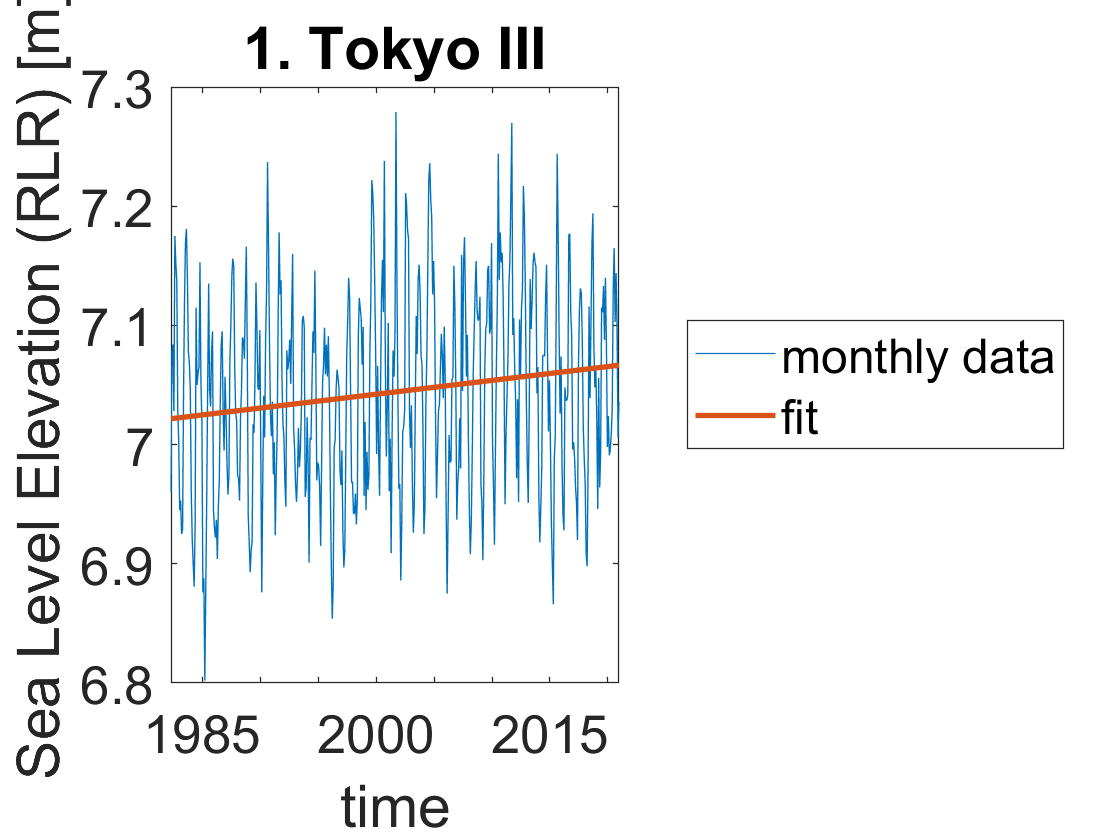

SLR for gauge 1. Tokyo III from 04/16/1982 to 12/15/2020 is 0.11588 cm/y.


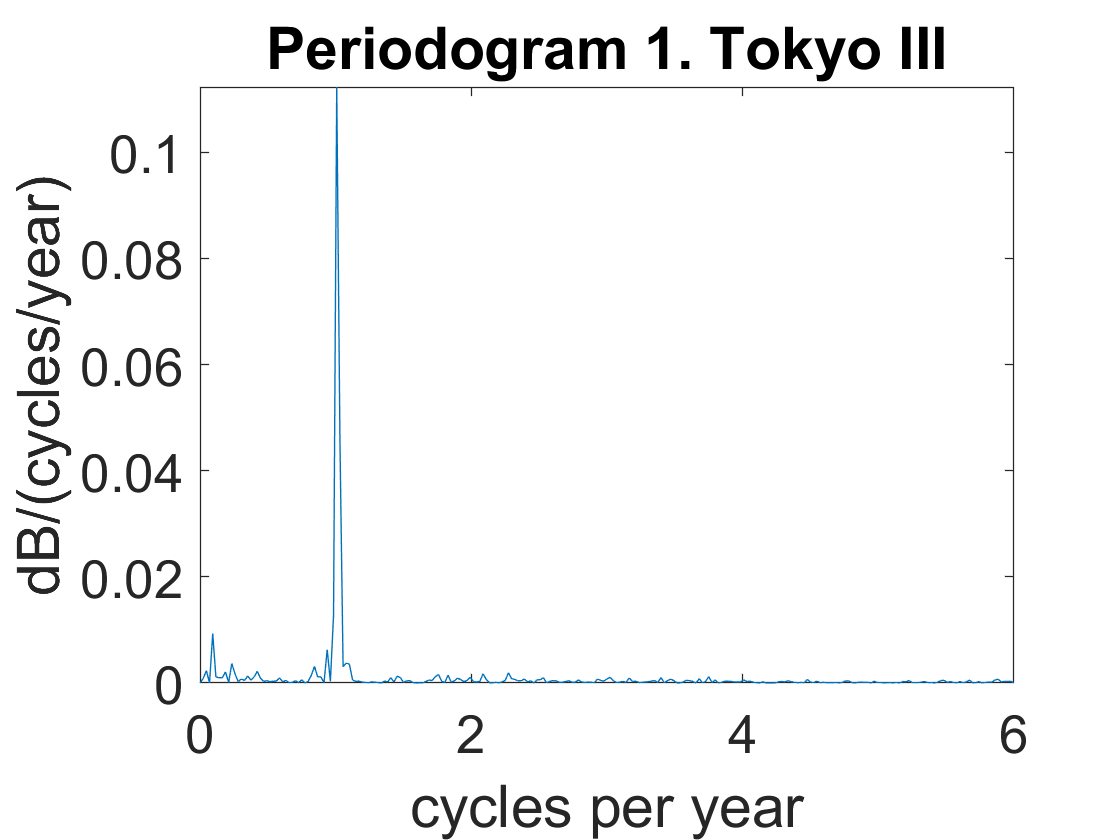

%1. Tokyo III
[date1, SL1] = readGauge(path1);

[regsol1, linreg1] = analyze(date1, SL1, '1. Tokyo III');

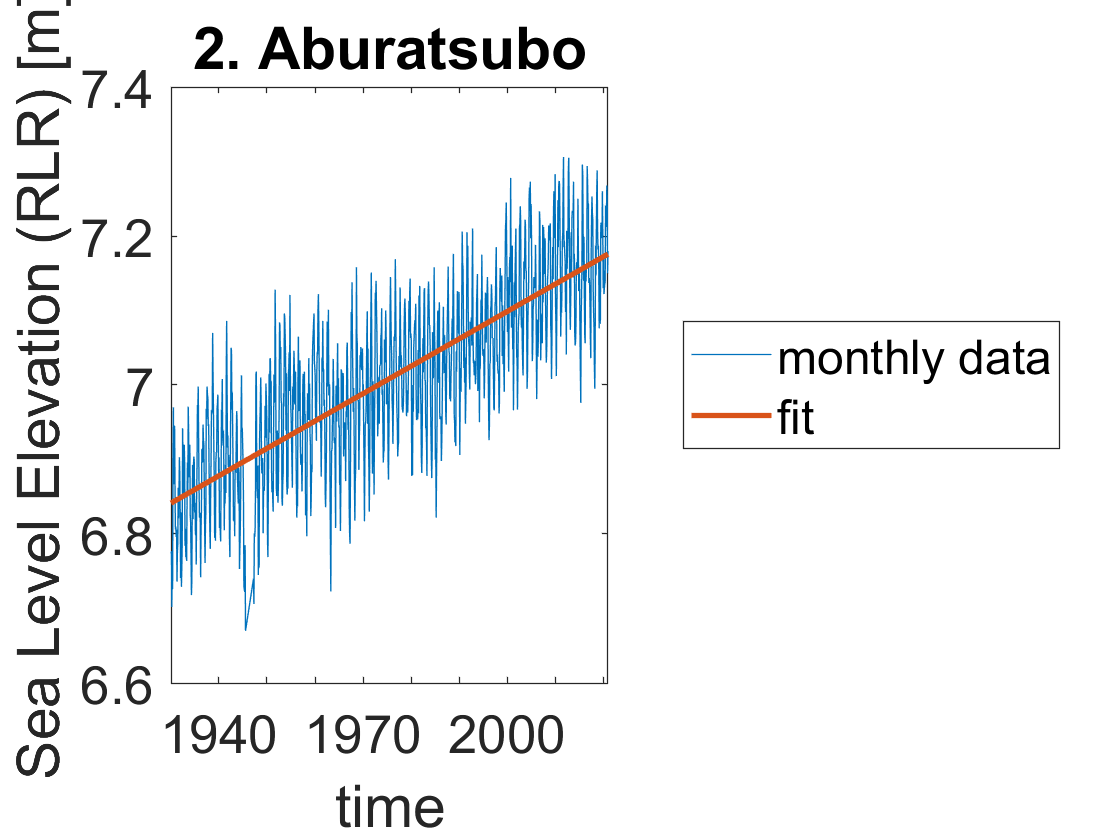

SLR for gauge 2. Aburatsubo from 01/15/1930 to 12/15/2020 is 0.36746 cm/y.


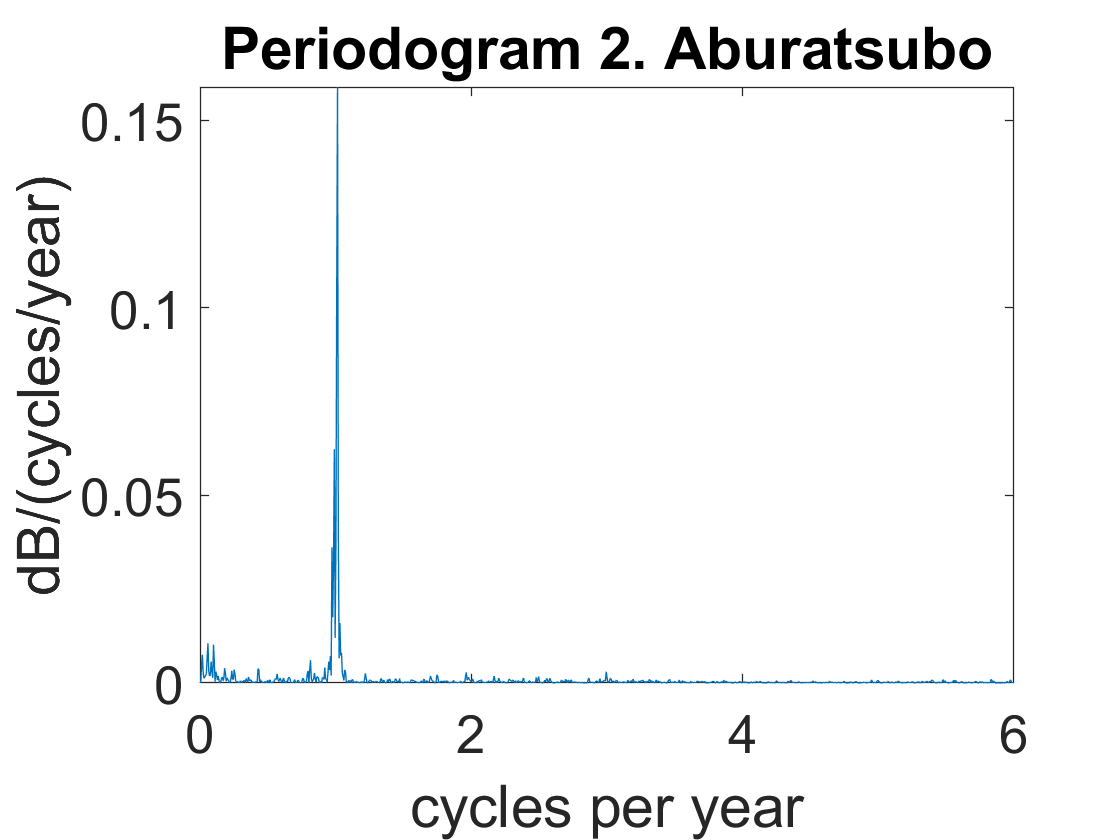

%2. Aburatsubo
[date2, SL2] = readGauge(path2);

[regsol2, linreg2] = analyze(date2, SL2, '2. Aburatsubo');

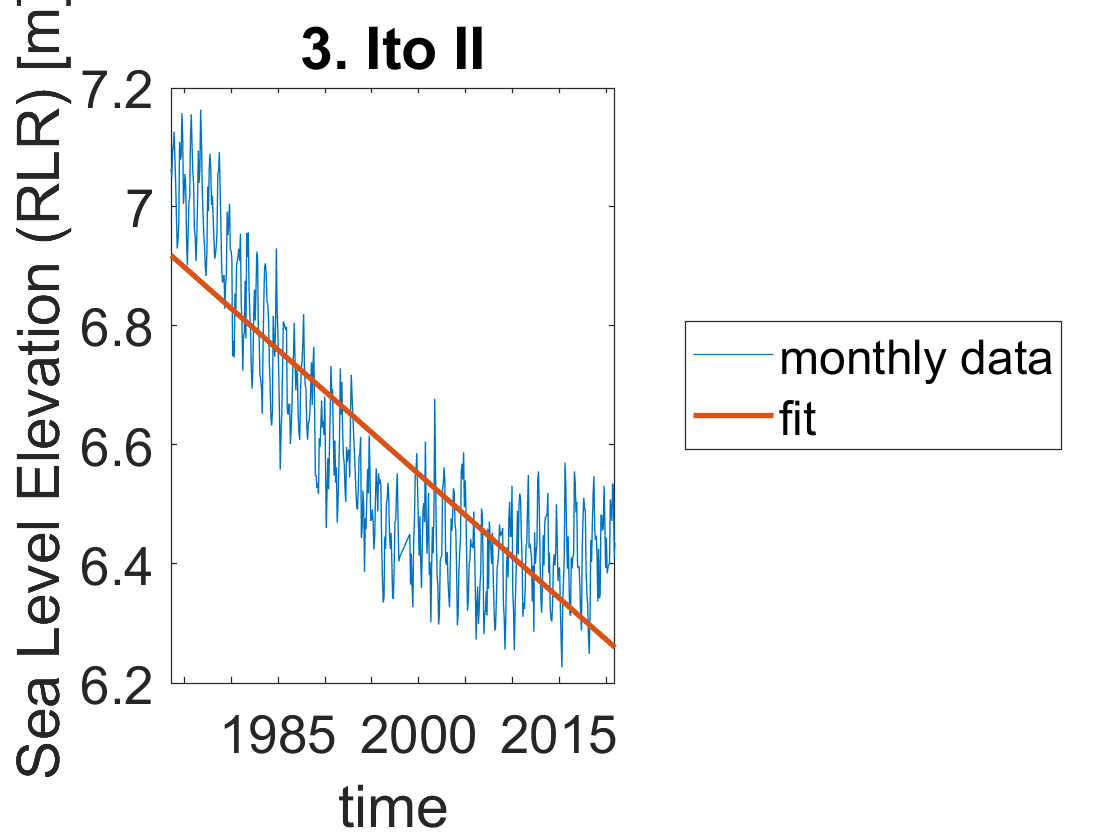

SLR for gauge 3. Ito II from 07/16/1973 to 12/15/2020 is -1.3863 cm/y.


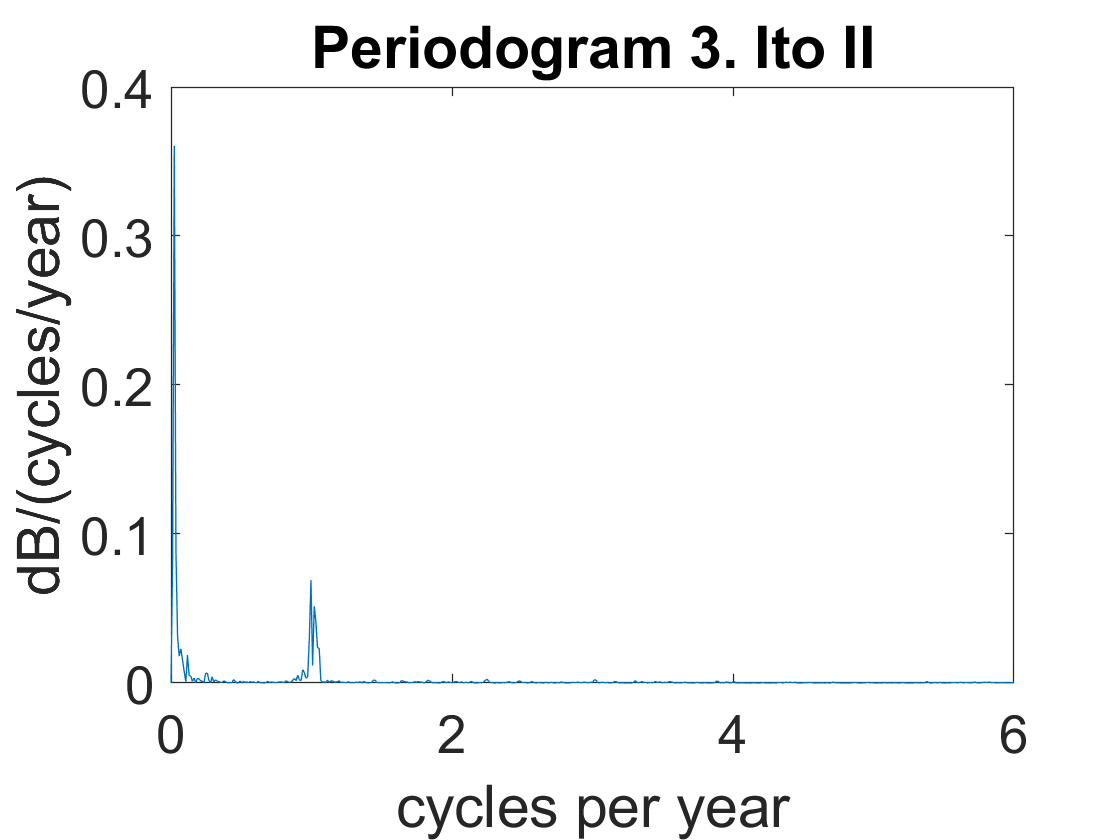

%3. Ito II
[date3, SL3] = readGauge(path3);

[regsol3, linreg3] = analyze(date3, SL3, '3. Ito II');

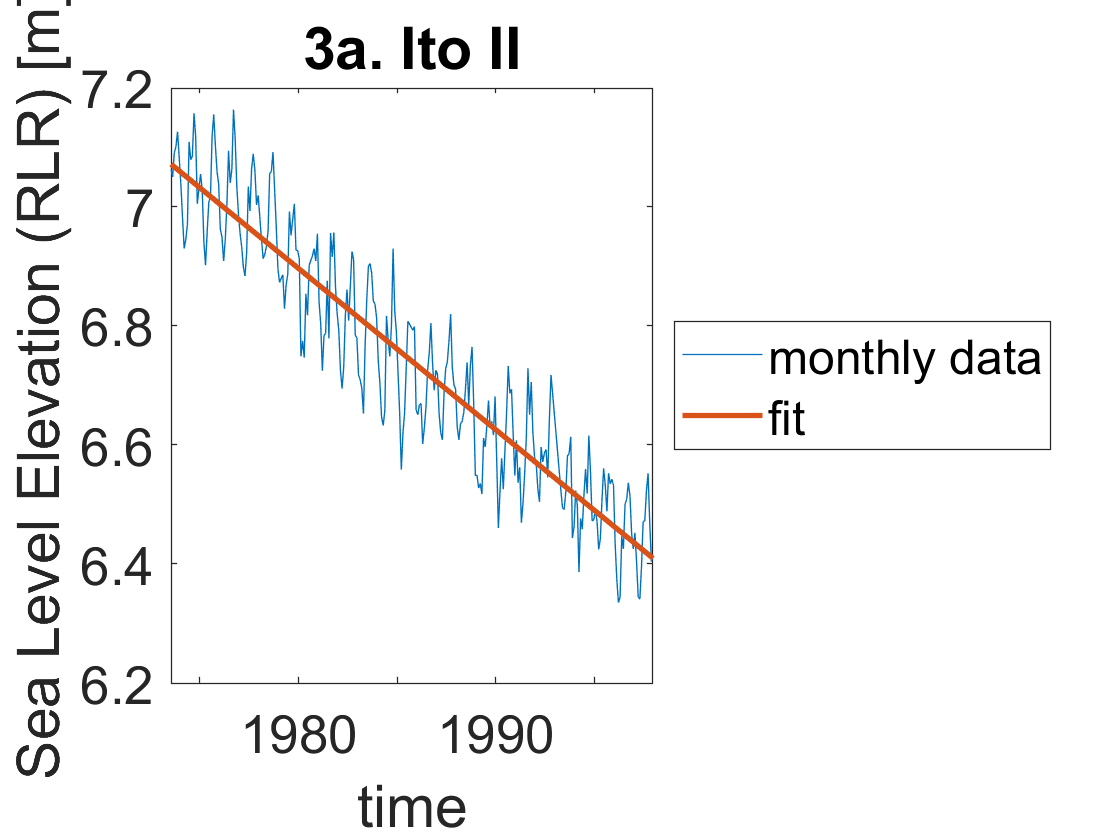

SLR for gauge 3a. Ito II from 07/16/1973 to 12/15/1997 is -2.706 cm/y.


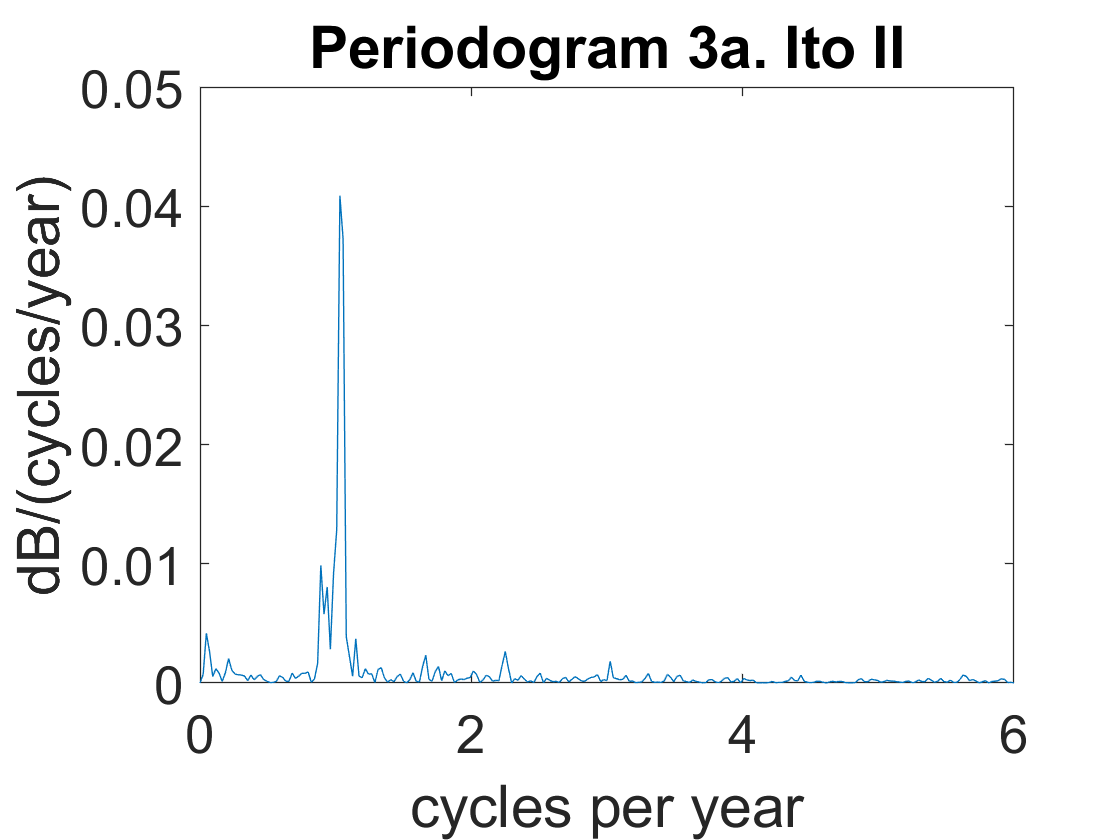

%%3a. Ito II; 16 Jul 1973 to 15 Dec 1997
[date3a, SL3a, date3b, SL3b] = cleave(date3, SL3, datetime(1997, 12, 16));

[regsol3a, linreg3a] = analyze(date3a, SL3a, '3a. Ito II');

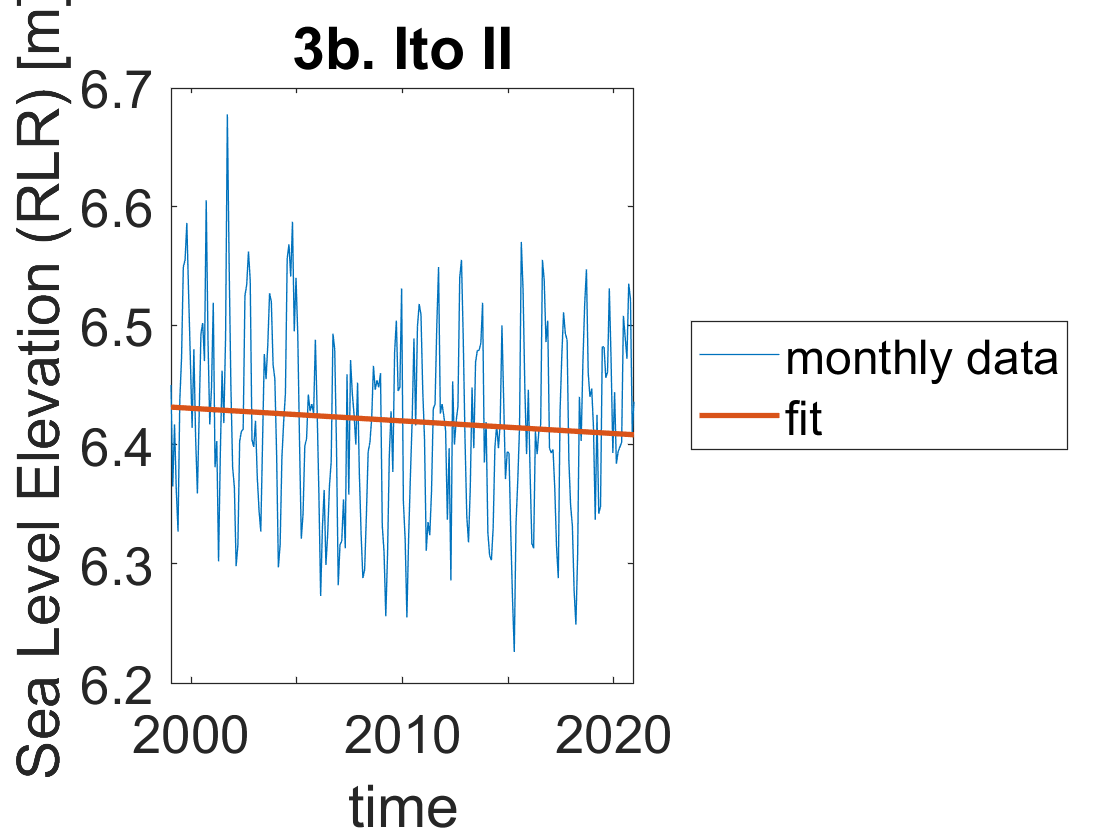

SLR for gauge 3b. Ito II from 01/15/1999 to 12/15/2020 is -0.10577 cm/y.


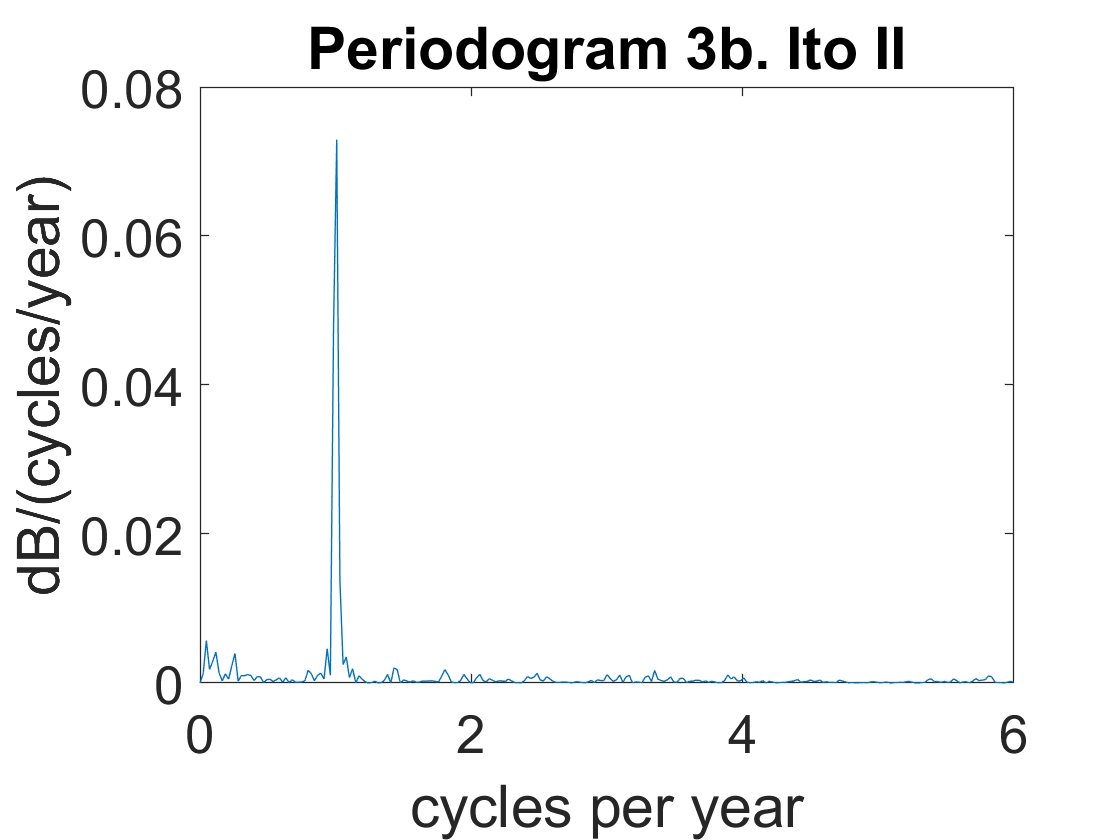

%%3b. Ito II; 15 Jan 1999 to 15 Dec 2020
%there is a skip between 1997 and 1999
[regsol3b, linreg3b] = analyze(date3b, SL3b, '3b. Ito II');

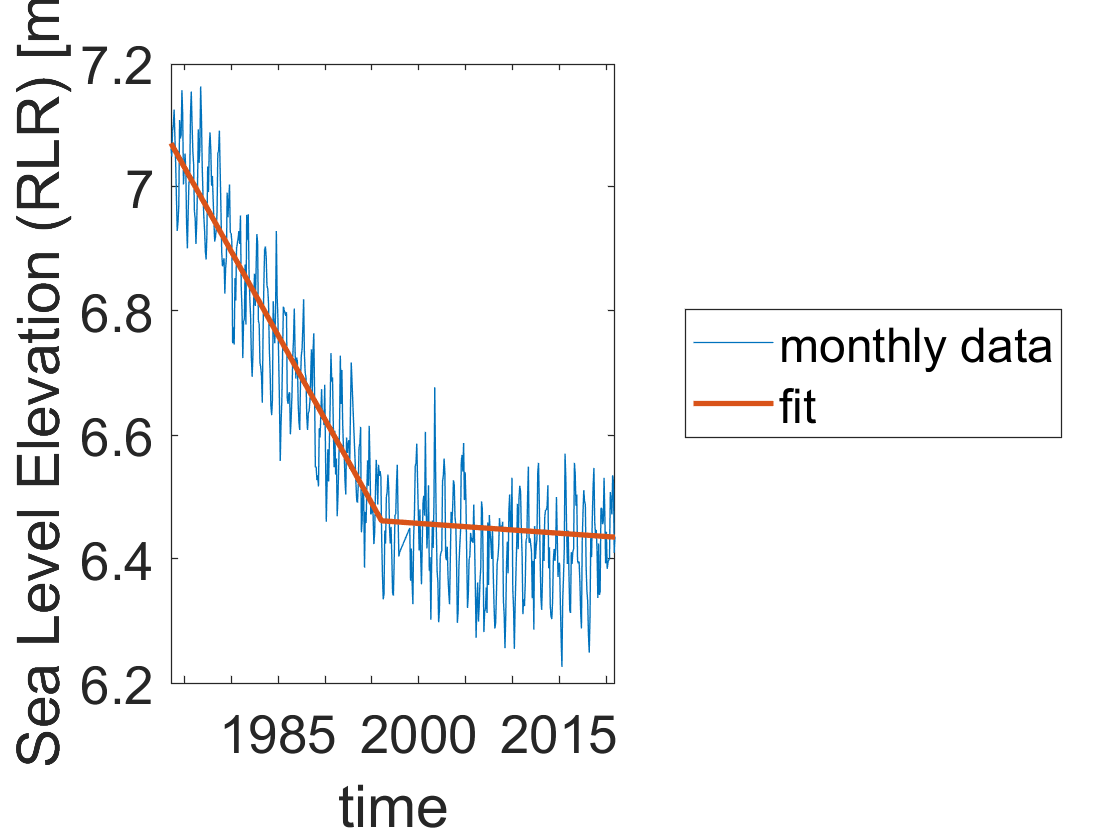

%3. Stitch together Ito II graphs
[x_vals3, y_vals3] = stitchReg(date3a, date3b, regsol3a, regsol3b);

%plot data together
figure
plot(date3, SL3)
hold on
plot(x_vals3, y_vals3, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off

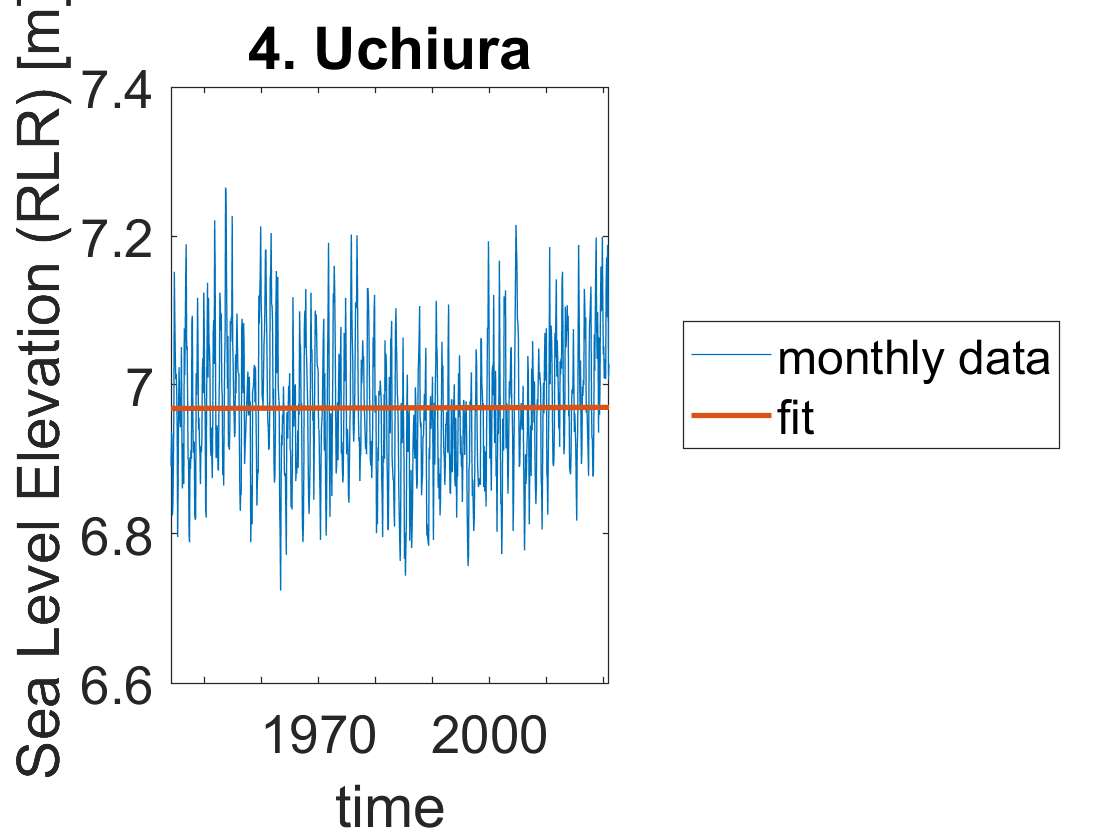

SLR for gauge 4. Uchiura from 01/15/1944 to 12/15/2020 is 0.0018307 cm/y.


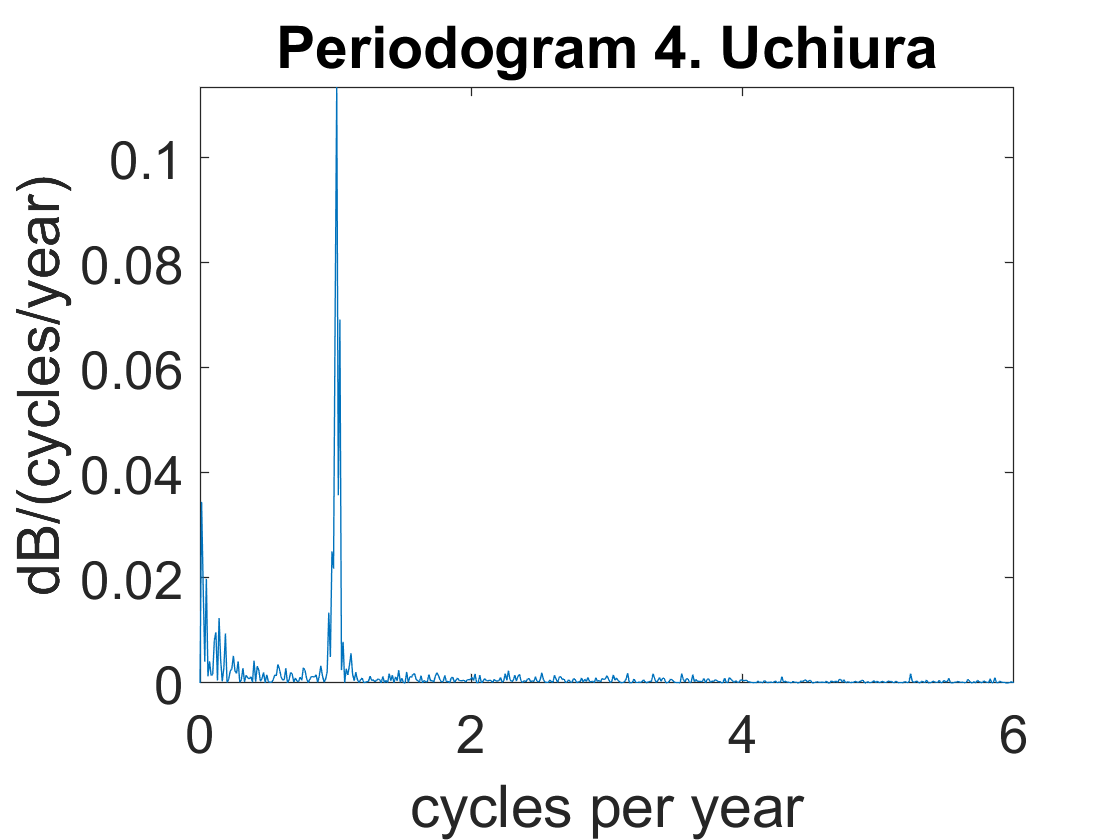

%4. Uchiura
[date4, SL4] = readGauge(path4);

[regsol4, linreg4] = analyze(date4, SL4, '4. Uchiura');

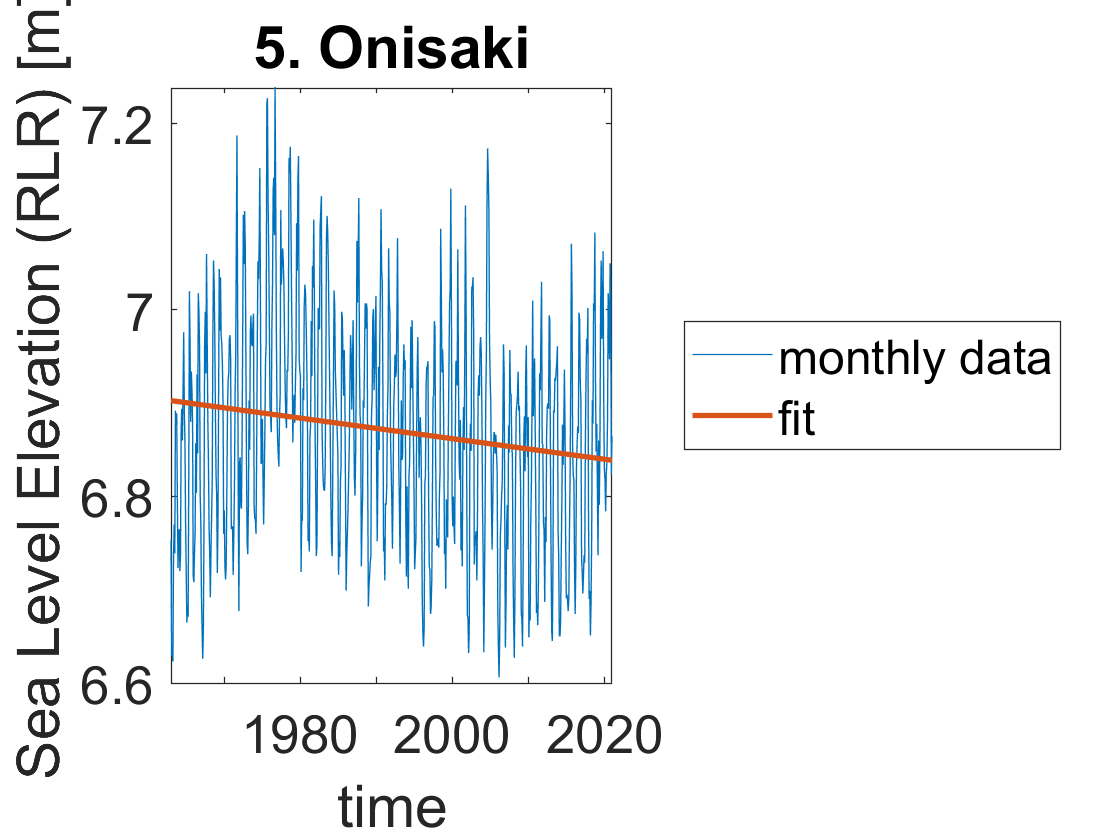

SLR for gauge 5. Onisaki from 01/15/1963 to 12/15/2020 is -0.11031 cm/y.


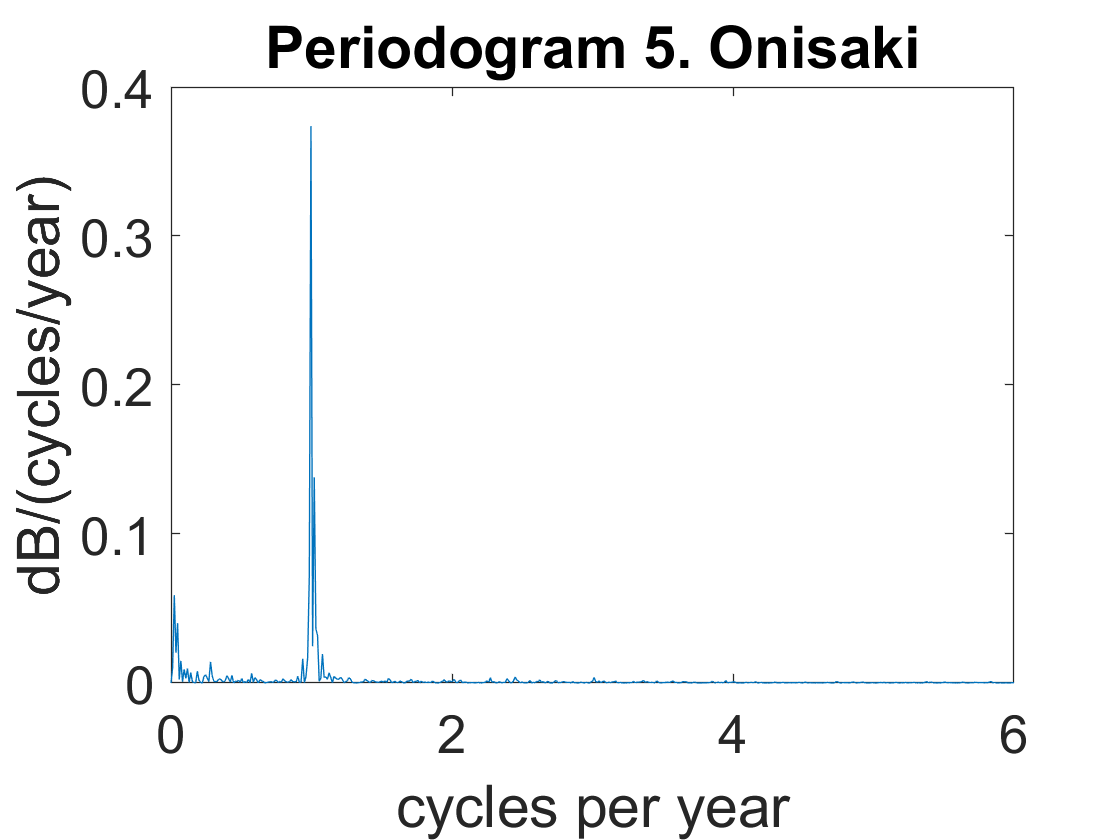

%5. Onisaki
[date5, SL5] = readGauge(path5);

[regsol5, linreg5] = analyze(date5, SL5, '5. Onisaki');

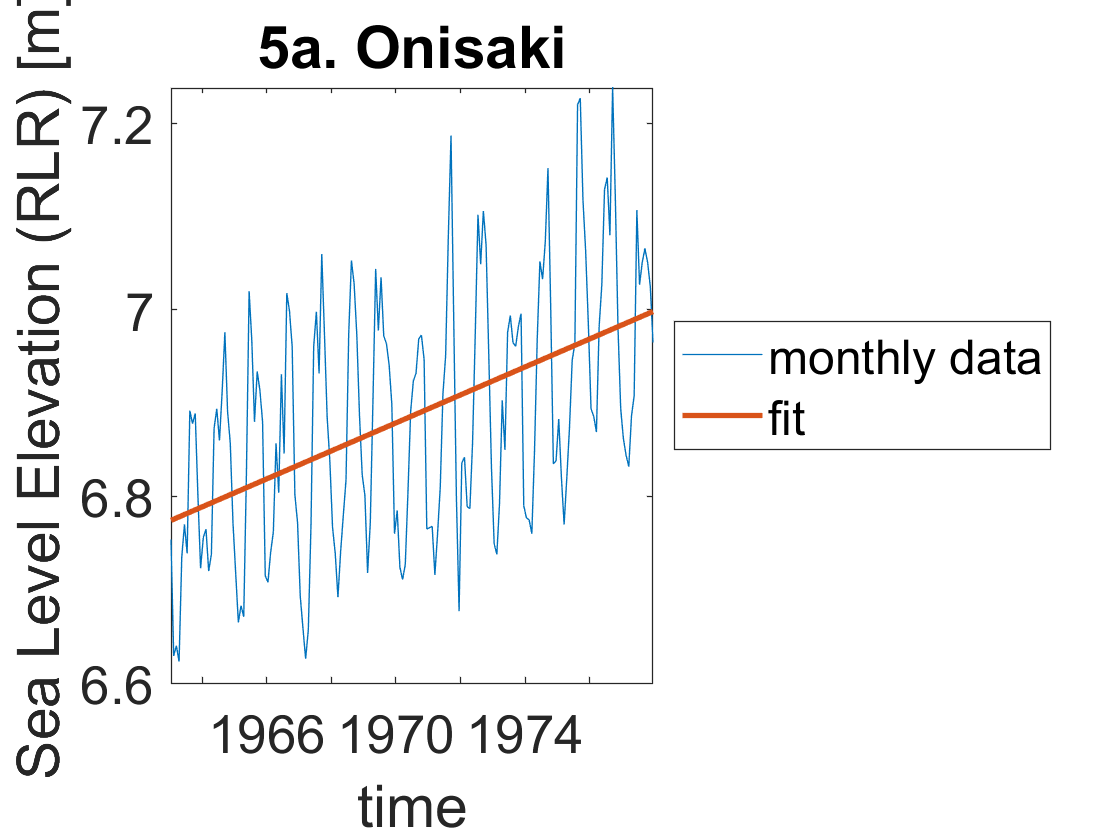

SLR for gauge 5a. Onisaki from 01/15/1963 to 12/15/1977 is 1.5001 cm/y.


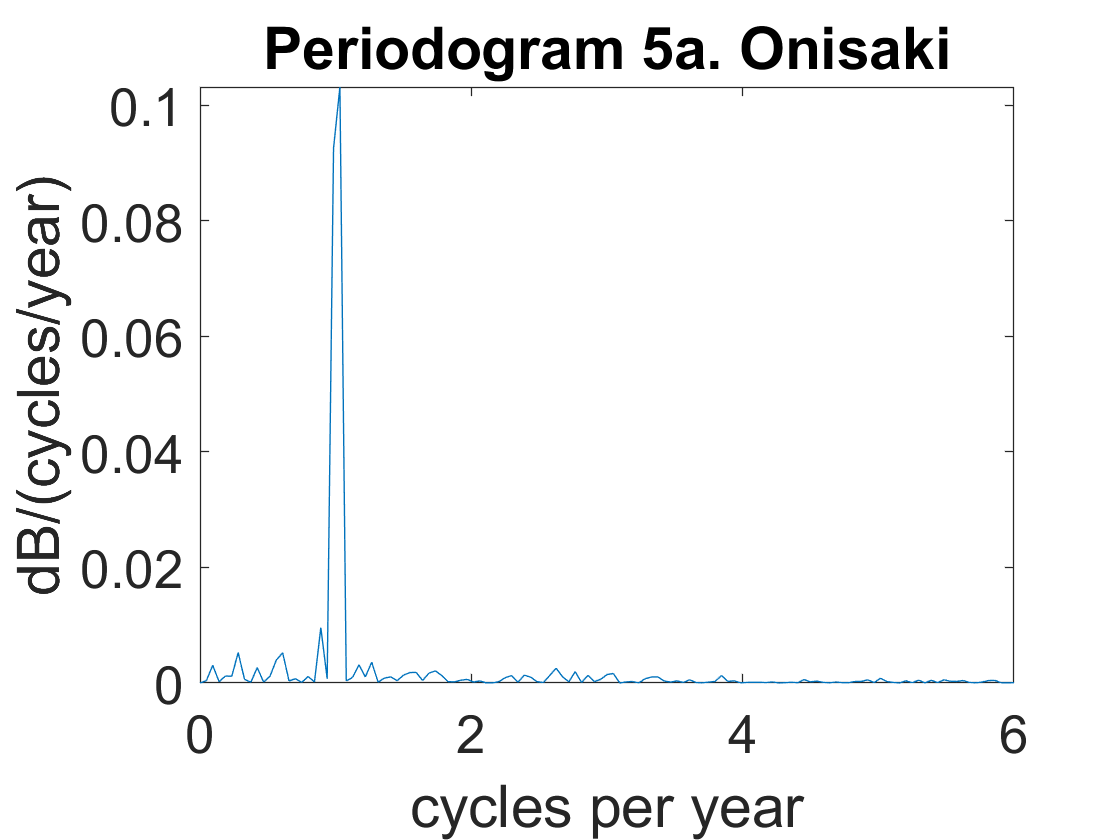

%%5a. Onisaki; 15 Jan 1963 to 15 Dec 1977
[date5a, SL5a, date5b, SL5b] = cleave(date5, SL5, datetime(1977, 12, 16));

[regsol5a, linreg5a] = analyze(date5a, SL5a, '5a. Onisaki');

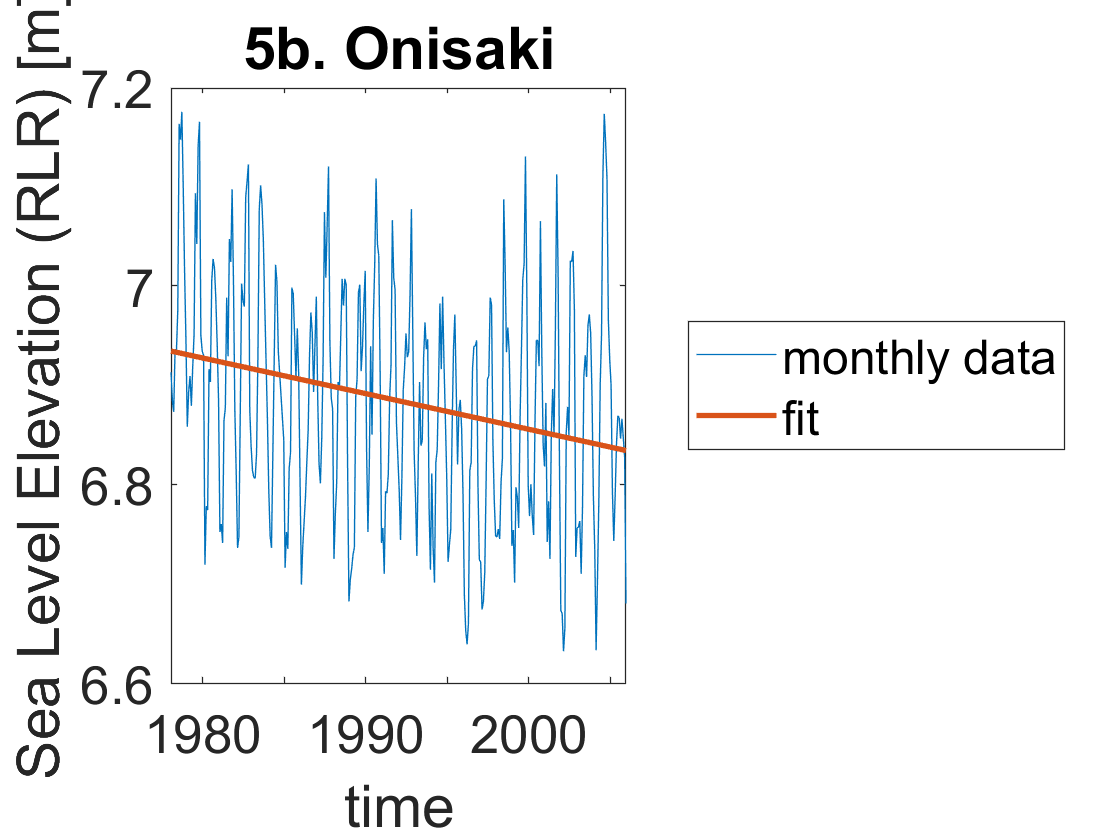

SLR for gauge 5b. Onisaki from 01/15/1978 to 12/15/2005 is -0.35836 cm/y.


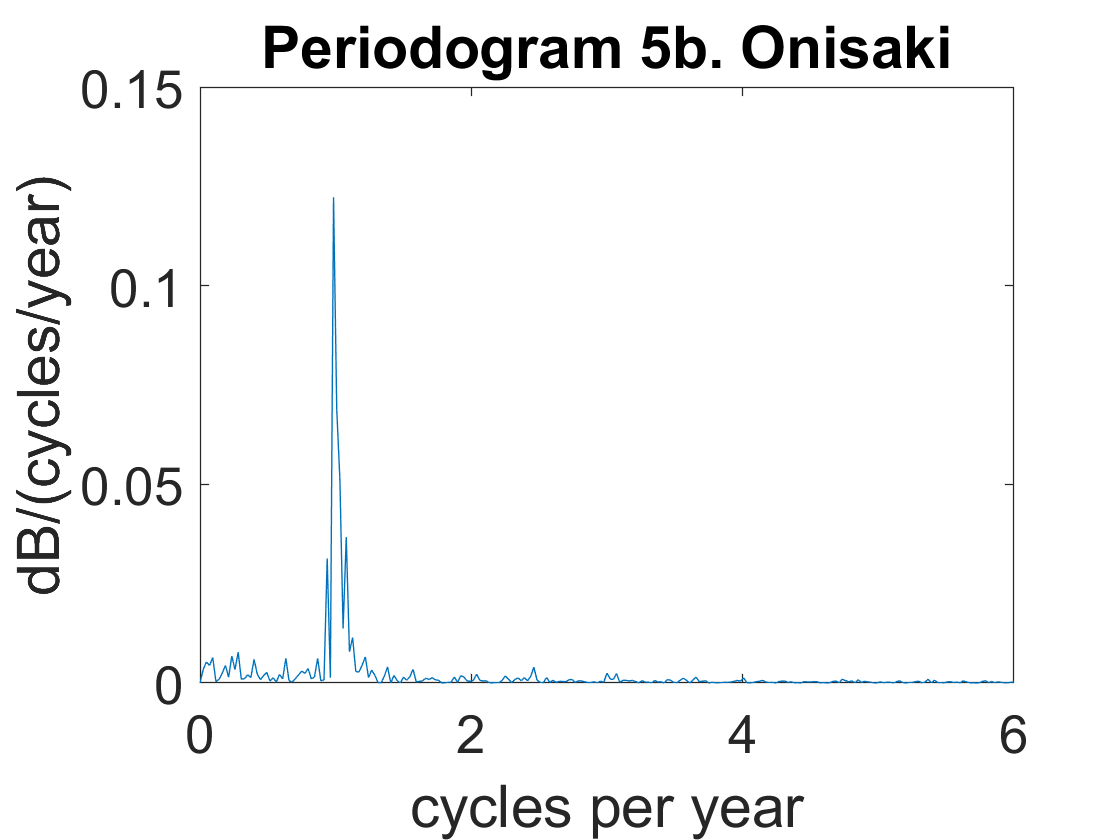

%%5b. Onisaki; 15 Jan 1978 to 15 Dec 2005
[date5b, SL5b, date5c, SL5c] = cleave(date5b, SL5b, datetime(2005, 12, 16));

[regsol5b, linreg5b] = analyze(date5b, SL5b, '5b. Onisaki');

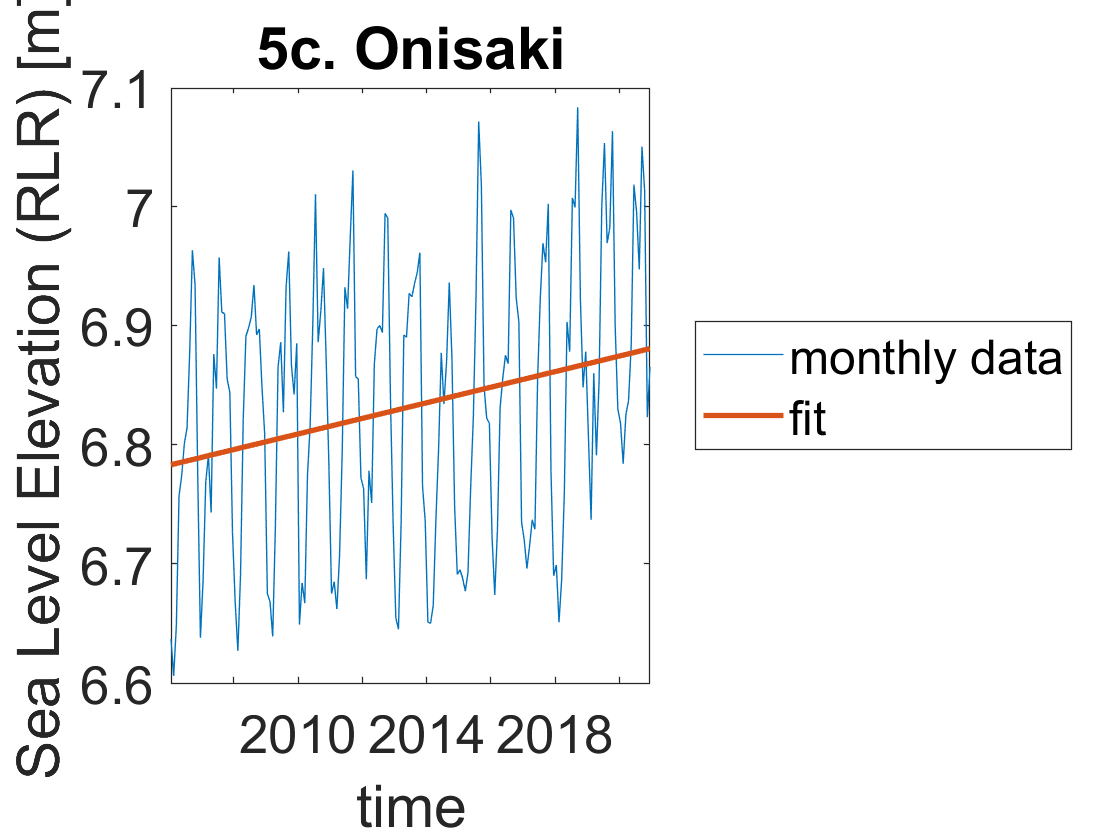

SLR for gauge 5c. Onisaki from 01/15/2006 to 12/15/2020 is 0.65284 cm/y.


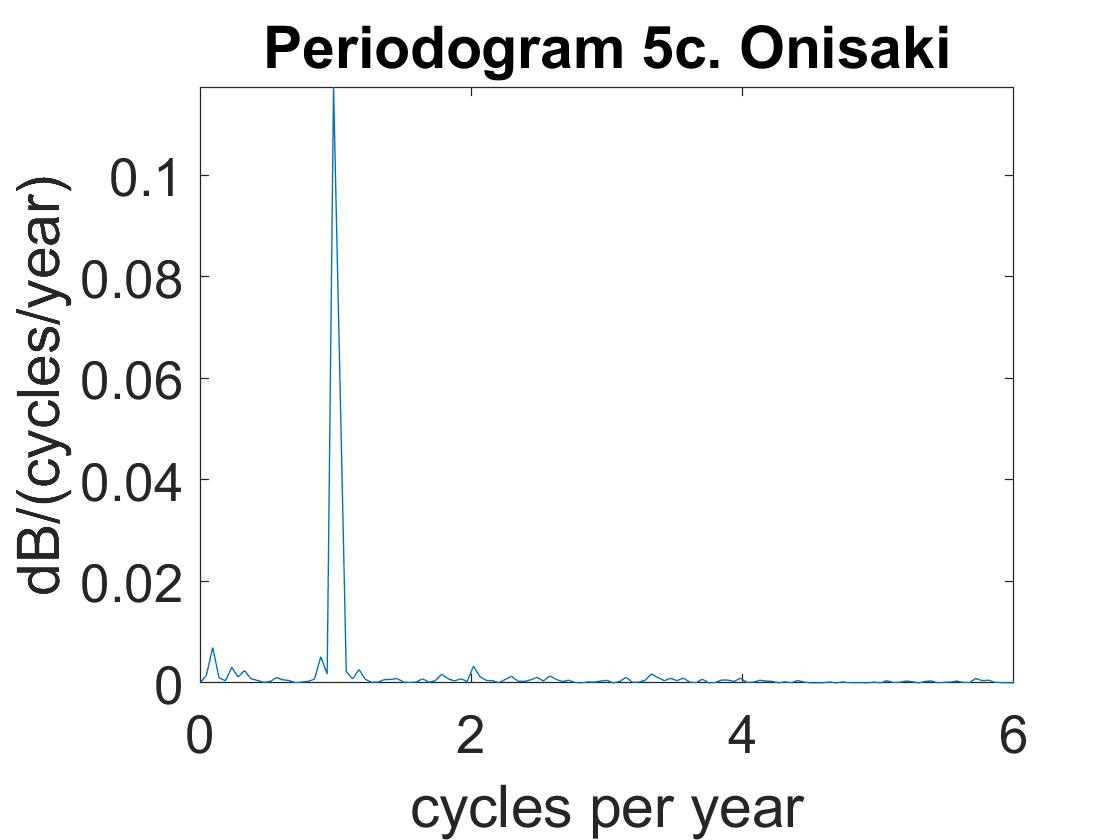

%%5c. Onisaki; 15 Jan 2006 to 15 Dec 2020
[regsol5c, linreg5c] = analyze(date5c, SL5c, '5c. Onisaki');


linreg_combo_5 = [linreg5a; linreg5b; linreg5c];

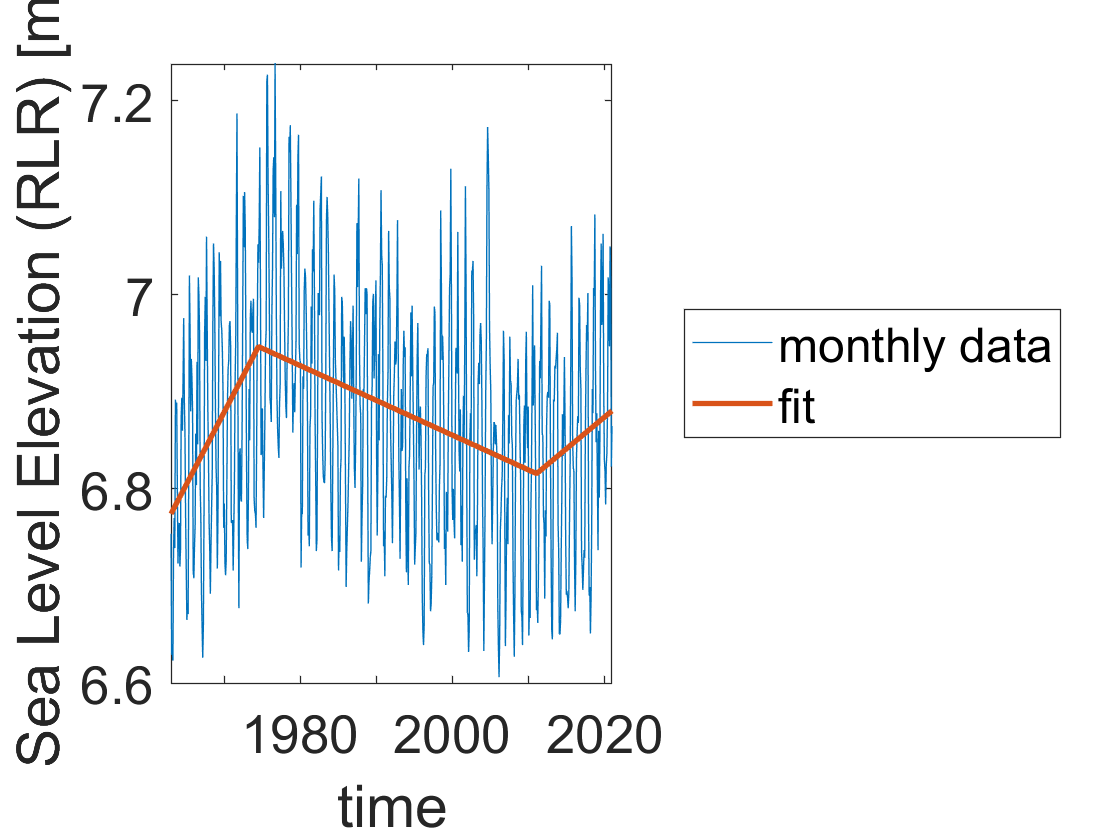

%3. Stitch together Onisaki graphs
[x_vals5, y_vals5] = stitchReg(date5a, date5b, regsol5a, regsol5b);

%get creative with stitching
[x_vals5_2, y_vals5_2] = stitchReg(date5b, date5c, regsol5b, regsol5c);
%combine the two sitches
x_vals5 = [x_vals5(1:end-1), x_vals5_2(2:end)];
y_vals5 = [y_vals5(1:end-1), y_vals5_2(2:end)];

%plot data together
figure
plot(date5, SL5)
hold on
plot(x_vals5, y_vals5, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off

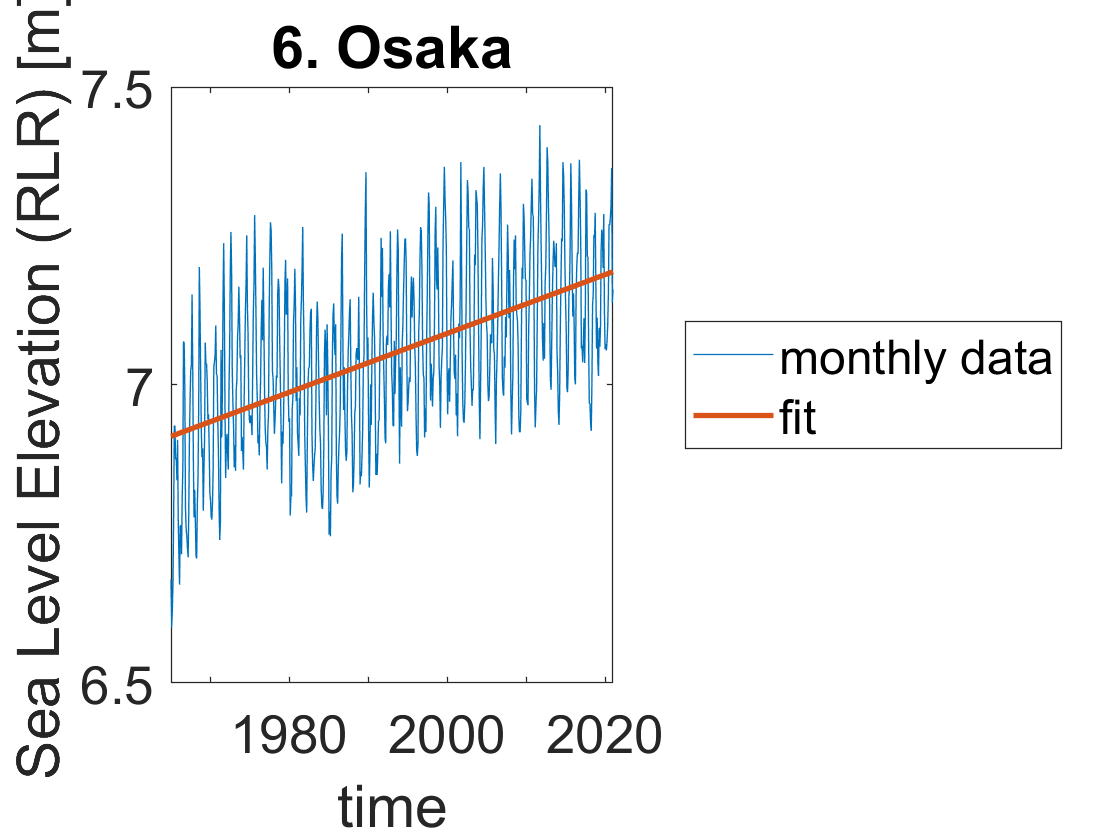

SLR for gauge 6. Osaka from 01/15/1965 to 12/15/2020 is 0.4938 cm/y.


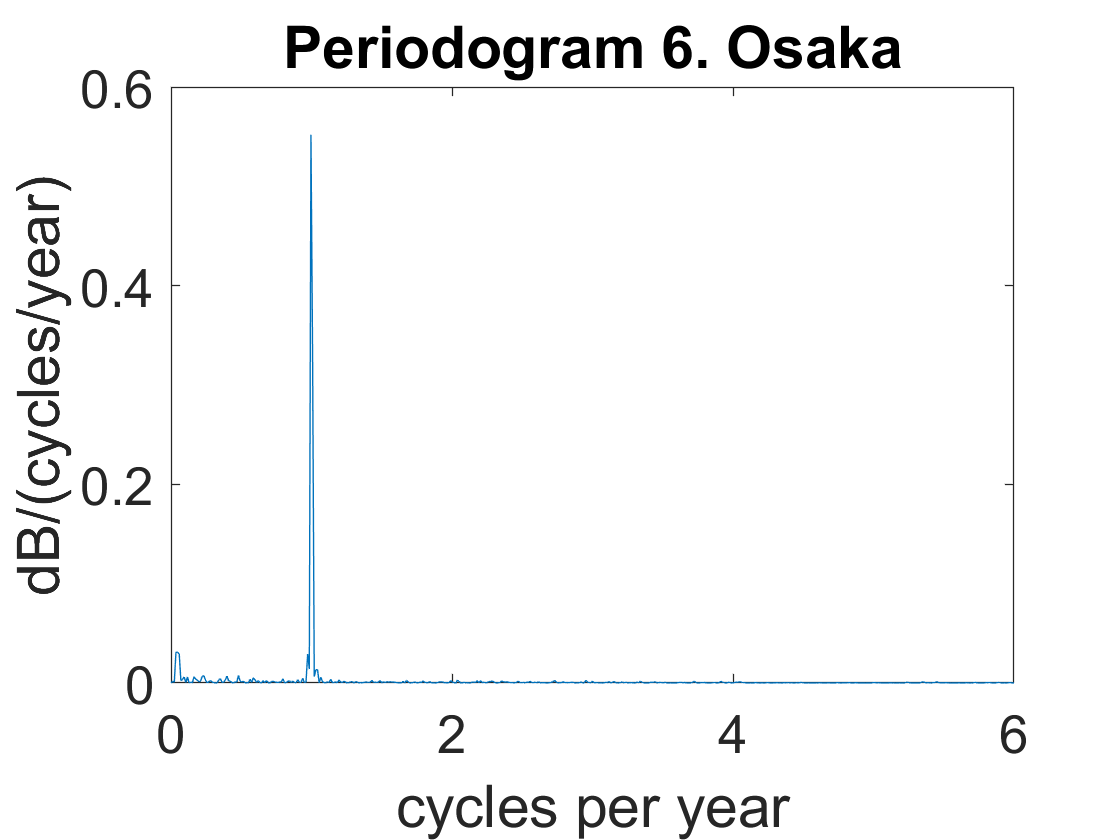

%6. Osaka
[date6, SL6] = readGauge(path6);

[regsol6, linreg6] = analyze(date6, SL6, '6. Osaka');

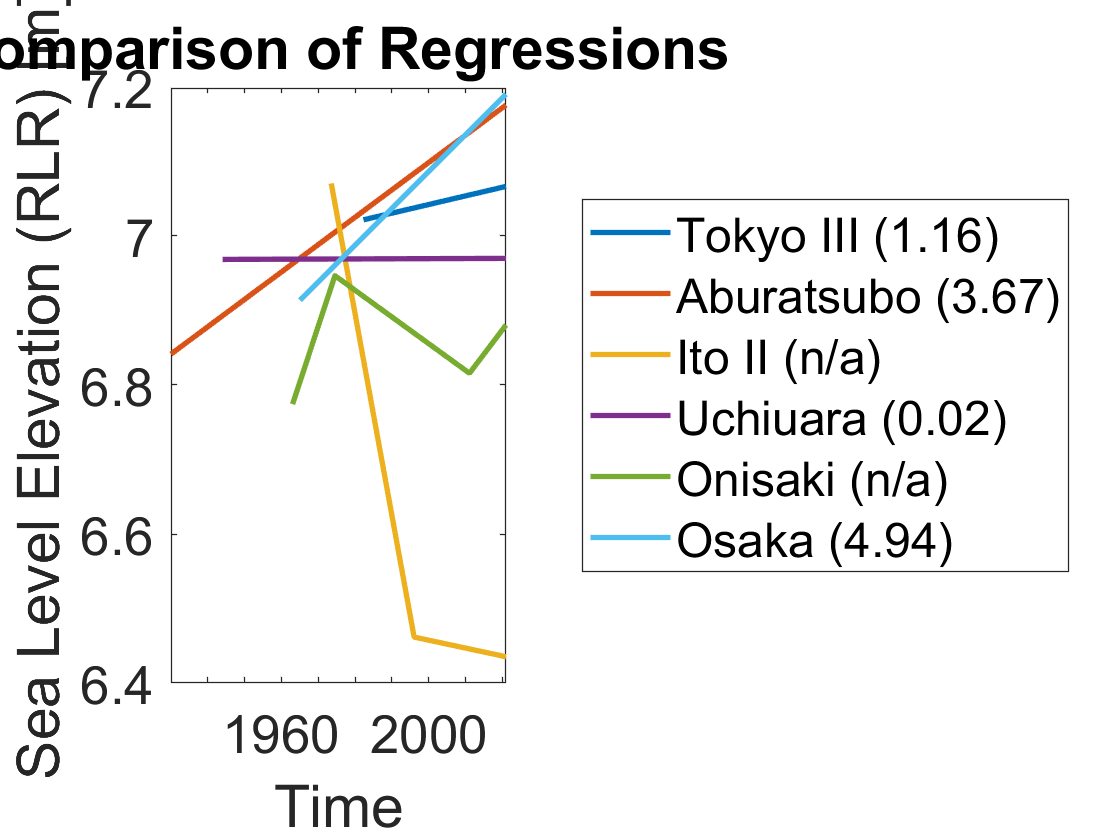

%plot all regressions on one graph
plot(date1, linreg1, 'LineWidth', 2)
hold on
plot(date2, linreg2, 'LineWidth', 2)
plot(x_vals3, y_vals3, 'LineWidth', 2)
plot(date4, linreg4, 'LineWidth', 2)
plot(x_vals5, y_vals5, 'LineWidth', 2)
plot(date6, linreg6, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('Time')
ylabel('Sea Level Elevation (RLR) [m]')
title('Comparison of Regressions')
legend('Tokyo III (1.16)', 'Aburatsubo (3.67)', 'Ito II (n/a)', 'Uchiuara (0.02)', 'Onisaki (n/a)', 'Osaka (4.94)', 'location', 'eastoutside')
hold off

function [date, SL] = readGauge(path)
%takes data from PSMSL and outputs dates corresponding to SL

%read data
read = readtable(path);
raw = table2array(read);

date = num2cell(ones(size(raw)));
SL = num2cell(ones(size(raw)));

%take out date and SL data
for i = 1:length(raw)
    strings = split(raw{i}, ';');
    date(i) = strings(1);
    SL(i) = strtrim(strings(2));
end

%convert to double
date = str2double(date);
SL = str2double(SL);

%remove null SL
null_ind = SL == -99999;
date(null_ind) = [];
SL(null_ind) = [];

%convert date to datetime
year = floor(date);
secs = (date - year).*(365 + isleapyr(year)).*24.*3600;
date = datetime(year, 1, 0, 0, 0, secs);

%SL to m
SL = SL/1000;
end

function [regsol, linreg] = analyze(date, SL, label)
%performs all necessary analysis

%%linear regression
num = datenum(date);
A(:, 1) = (num - num(1))/365;
A(:, 2) = 1;
regsol = A\SL;
linreg = regsol(1).*A(:, 1) + regsol(2);

figure
plot(date, SL)
hold on
plot(date, linreg, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title(label)
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off

%slope of regression [cm/y]
out = 'mm/dd/yyyy';
printStr = ['SLR for gauge ', label, ' from ', datestr(date(1), out) ,' to ', datestr(date(end), out), ' is ', num2str(regsol(1)*100), ' cm/y.'];
disp(printStr)

%%periodogram
%normalize data from trend
SL_noSLR = SL - linreg;

%PSD calcs
[pxx, f] = periodogram(SL_noSLR, [], [], 12);

figure
plot(f, pxx)
set(gca, 'fontsize', 20)
title(['Periodogram ' label])
xlabel('cycles per year')
ylabel('dB/(cycles/year)')
end

function [date_beg, SL_beg, date_end, SL_end] = cleave(inDate, inSL, separator)
%returns data from beginning to separator date, inclusive, and the rest
ind = inDate <= separator;

%returns beginning
date_beg = inDate(ind);
SL_beg = inSL(ind);

%returns end
date_end = inDate(~ind);
SL_end = inSL(~ind);
end

function [x_vals, y_vals] = stitchReg(date1, date2, regsol1, regsol2)
%normalize all date numbers
num1 = datenum(date1);
num2 = datenum(date2);
reference = num1(1);
num1 = (num1 - reference)/365;
num2 = (num2 - reference)/365;

%extrapolate "later" regression back to the start of the other 
regsol2(2) = regsol2(2) - regsol2(1)*num2(1);

%calculate x of intersection 
xc = (regsol2(2) - regsol1(2))/(regsol1(1) - regsol2(1));

%make vector of 3 relevant x values
x_vals = [num1(1), xc, num2(end)];
%make vector of 3 relevant y values
y_vals = [regsol1(2), xc*regsol1(1) + regsol1(2), num2(end)*regsol2(1) + regsol2(2)];

%convert x_vals to datetime
x_vals = datetime(reference + x_vals*365, 'convertFrom', 'datenum');
end

function is = isleapyr(yr)
%  returns T for input year being a leapyear
%  dpbozarth       Rev 0   07Jun1998  Initial
%                  Rev 1   31Mar2005  Use eomday() vs number days in year
%                  Rev 2   04Feb2015  Handle new datetime class
if isdatetime(yr), yr=year(yr); end
is=eomday(yr,2)==29;
end